# Part 1- Implementing FFT 

Defining a signal

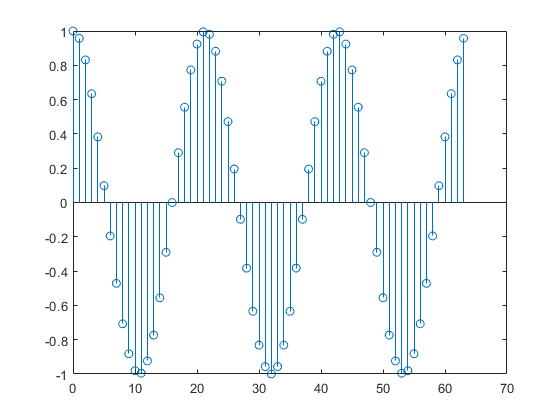

N = 64; 
n = 0:N-1;
x = cos(2*pi*3*n/N);
stem(n,x);

Find it's transform

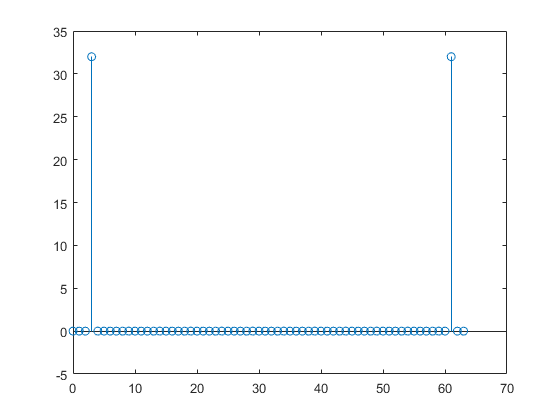

X = calc_fft(x);
stem(n,X);

Find the inverse transform (the signal itself) 

y = calc_ifft(X);
stem(n,y);

Ploting the error of the calculation

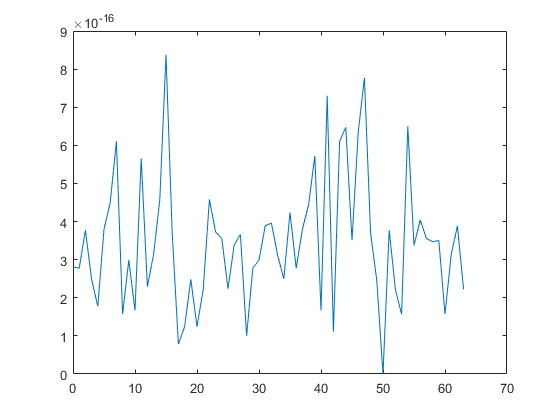

plot(n,abs(x-y))

The FFT function

function X_k = calc_fft(x_n)
    L = size(x_n,2);
    
    % If the series is with length 1 it's DFT is exactly the series itself
    if(L == 1)
        X_k = x_n;
        return;
    end 
    
    % Pad the signal with zeros 
    if(floor(log2(L)) ~= log2(L))
        x_n = [x_n,zeros(1,2^(ceil(log2(L)))-L)];
    end
    
    % Find the DFT of the even part
    g_n = x_n(1:2:end); 
    G_k = calc_fft(g_n);
    G_k = [G_k, G_k];
    
    % Find the DFT of the odd part
    h_n = x_n(2:2:end); 
    H_k = calc_fft(h_n);
    H_k = [H_k,H_k];
    
    % Merge the transforms into one vector
    N = size(x_n,2);
    k = 0:N-1;
    X_k = G_k + exp(-1i*2*pi.*k./N).*H_k;
    X_k = X_k(1:L);    
end 


The inverse FFT function

function x_n = calc_ifft(X_k)
    x_n = 1/size(X_k,2) * calc_fft(conj(X_k));
end 